%% Initialisation
clc
clearvars 
close all   

% Set LaTeX as default interpreter for axis labels, ticks and legends
set(0,'defaulttextinterpreter','latex')
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

set(0,'DefaultFigureWindowStyle','docked');
set(0,'defaultAxesFontSize',  16)
set(0,'DefaultLegendFontSize',16)

addpath('dataset/')


to_rad = pi/180;
to_deg = 180/pi;
%% Select tyre dataset
%dataset path
data_set_path = 'dataset/';
% dataset selection and loading

%data_set = 'B1464run23'; % pure lateral forces
data_set = 'Hoosier_B1464run30';  % braking/traction (pure log. force) + combined

% tyre geometric data:
% Hoosier	18.0x6.0-10
% 18 diameter in inches
% 6.0 section width in inches
% tread width in inches
diameter = 18*2.56; %
Fz0 = 220;   % [N] nominal load is given
R0  = diameter/2/100; % [m] get from nominal load R0 (m) *** TO BE CHANGED ***


fprintf('Loading dataset ...')

Loading dataset ...

switch data_set
  case 'B1464run23'
  load ([data_set_path, 'B1464run23.mat']); % pure lateral
  cut_start = 27760;
  cut_end   = 54500;
  case 'Hoosier_B1464run30'
  load ([data_set_path, 'Hoosier_B1464run30.mat']); % pure longitudinal
  cut_start = 19028;
  cut_end   = 37643;
  otherwise 
  error('Not found dataset: `%s`\n', data_set) ;
  
end

% select dataset portion
smpl_range = cut_start:cut_end;

fprintf('completed!\n')

completed!


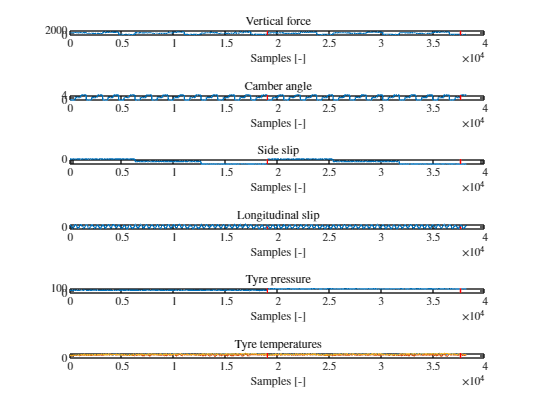

%% Plot raw data

figure
tiledlayout(6,1)

ax_list(1) = nexttile; y_range = [min(min(-FZ),0) round(max(-FZ)*1.1)];
plot(-FZ)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Vertical force')
xlabel('Samples [-]')
ylabel('[N]')

ax_list(2) = nexttile; y_range = [min(min(IA),0) round(max(IA)*1.1)];
plot(IA)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Camber angle')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list(3) = nexttile; y_range = [min(min(SA),0) round(max(SA)*1.1)];
plot(SA)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Side slip')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list(4) = nexttile; y_range = [min(min(SL),0) round(max(SL)*1.1)];
plot(SL)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Longitudinal slip')
xlabel('Samples [-]')
ylabel('[-]')

ax_list(5) = nexttile; y_range = [min(min(P),0) round(max(P)*1.1)];
plot(P)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Tyre pressure')
xlabel('Samples [-]')
ylabel('[psi]')

ax_list(6) = nexttile;  y_range = [min(min(TSTC),0) round(max(TSTC)*1.1)];
plot(TSTC,'DisplayName','Center')
hold on
plot(TSTI,'DisplayName','Internal')
plot(TSTO,'DisplayName','Outboard')
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Tyre temperatures')
xlabel('Samples [-]')
ylabel('[degC]')

linkaxes(ax_list,'x')

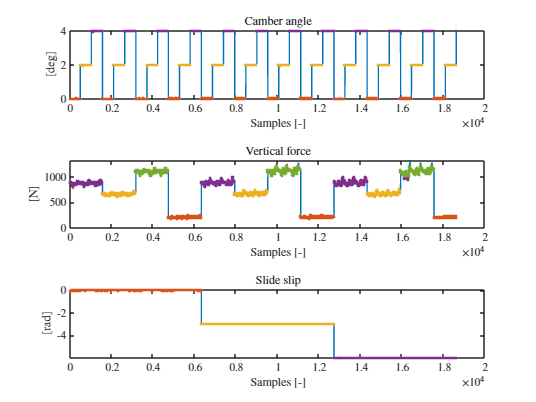



%plot(SA,FY)


%% Select some specific data
% Cut crappy data and select only 12 psi data

vec_samples = 1:1:length(smpl_range);
tyre_data = table(); % create empty table
% store raw data in table
tyre_data.SL =  SL(smpl_range);
tyre_data.SA =  SA(smpl_range)*to_rad;
tyre_data.FZ = -FZ(smpl_range);  % 0.453592  lb/kg
tyre_data.FX =  FX(smpl_range);
tyre_data.FY =  FY(smpl_range);
tyre_data.MZ =  MZ(smpl_range);
tyre_data.IA =  IA(smpl_range)*to_rad;

% Extract points at constant inclination angle
GAMMA_tol = 0.05*to_rad;
idx.GAMMA_0 = 0.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 0.0*to_rad+GAMMA_tol;
idx.GAMMA_1 = 1.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 1.0*to_rad+GAMMA_tol;
idx.GAMMA_2 = 2.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 2.0*to_rad+GAMMA_tol;
idx.GAMMA_3 = 3.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 3.0*to_rad+GAMMA_tol;
idx.GAMMA_4 = 4.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 4.0*to_rad+GAMMA_tol;
idx.GAMMA_5 = 5.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 5.0*to_rad+GAMMA_tol;
GAMMA_0  = tyre_data( idx.GAMMA_0, : );
GAMMA_1  = tyre_data( idx.GAMMA_1, : );
GAMMA_2  = tyre_data( idx.GAMMA_2, : );
GAMMA_3  = tyre_data( idx.GAMMA_3, : );
GAMMA_4  = tyre_data( idx.GAMMA_4, : );
GAMMA_5  = tyre_data( idx.GAMMA_5, : );

% Extract points at constant vertical load
% Test data done at: 
%  - 50lbf  ( 50*0.453592*9.81 =  223N )
%  - 150lbf (150*0.453592*9.81 =  667N )
%  - 200lbf (200*0.453592*9.81 =  890N )
%  - 250lbf (250*0.453592*9.81 = 1120N )

FZ_tol = 100;
idx.FZ_220  = 220-FZ_tol < tyre_data.FZ & tyre_data.FZ < 220+FZ_tol;
idx.FZ_440  = 440-FZ_tol < tyre_data.FZ & tyre_data.FZ < 440+FZ_tol;
idx.FZ_700  = 700-FZ_tol < tyre_data.FZ & tyre_data.FZ < 700+FZ_tol;
idx.FZ_900  = 900-FZ_tol < tyre_data.FZ & tyre_data.FZ < 900+FZ_tol;
idx.FZ_1120 = 1120-FZ_tol < tyre_data.FZ & tyre_data.FZ < 1120+FZ_tol;
FZ_220  = tyre_data( idx.FZ_220, : );
FZ_440  = tyre_data( idx.FZ_440, : );
FZ_700  = tyre_data( idx.FZ_700, : );
FZ_900  = tyre_data( idx.FZ_900, : );
FZ_1120 = tyre_data( idx.FZ_1120, : );

% The slip angle is varied continuously between -4 and +12° and then
% between -12° and +4° for the pure slip case

% The slip angle is varied step wise for longitudinal slip tests
% 0° , - 3° , -6 °
SA_tol = 0.5*to_rad;
idx.SA_0    =  0-SA_tol          < tyre_data.SA & tyre_data.SA < 0+SA_tol;
idx.SA_3neg = -(3*to_rad+SA_tol) < tyre_data.SA & tyre_data.SA < -3*to_rad+SA_tol;
idx.SA_6neg = -(6*to_rad+SA_tol) < tyre_data.SA & tyre_data.SA < -6*to_rad+SA_tol;
SA_0     = tyre_data( idx.SA_0, : );
SA_3neg  = tyre_data( idx.SA_3neg, : );
SA_6neg  = tyre_data( idx.SA_6neg, : );

figure()
tiledlayout(3,1)

ax_list(1) = nexttile;
plot(tyre_data.IA*to_deg)
hold on
plot(vec_samples(idx.GAMMA_0),GAMMA_0.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_1),GAMMA_1.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_2),GAMMA_2.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_3),GAMMA_3.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_4),GAMMA_4.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_5),GAMMA_5.IA*to_deg,'.');
title('Camber angle')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list(2) = nexttile;
plot(tyre_data.FZ)
hold on
plot(vec_samples(idx.FZ_220),FZ_220.FZ,'.');
plot(vec_samples(idx.FZ_440),FZ_440.FZ,'.');
plot(vec_samples(idx.FZ_700),FZ_700.FZ,'.');
plot(vec_samples(idx.FZ_900),FZ_900.FZ,'.');
plot(vec_samples(idx.FZ_1120),FZ_1120.FZ,'.');
title('Vertical force')
xlabel('Samples [-]')
ylabel('[N]')


ax_list(3) = nexttile;
plot(tyre_data.SA*to_deg)
hold on
plot(vec_samples(idx.SA_0),   SA_0.SA*to_deg,'.');
plot(vec_samples(idx.SA_3neg),SA_3neg.SA*to_deg,'.');
plot(vec_samples(idx.SA_6neg),SA_6neg.SA*to_deg,'.');
title('Slide slip')
xlabel('Samples [-]')
ylabel('[rad]')





%% Intersect tables to obtain specific sub-datasets

[TData0, ~] = intersect_table_data( SA_0, GAMMA_0, FZ_220 );

%[tableSelectedData, ~] = intersectTableData( KAPPA_00, GAMMA_00, VX_10 );
%[TDataSub, ~] = intersectTableData( ALPHA_00, GAMMA_00, VX_10, FZ_6500 );

%[tableSelectedData, ~] = intersectTableData( KAPPA_00, GAMMA_00, VX_10, FZ_6500 );

% get data for tyre deflection (radius) versus speed
%[TDataSubRho, ~] = intersectTableData( KAPPA_00, ALPHA_00, GAMMA_00, FZ_6500 );


%% plot_selected_data

figure('Name','Selected-data')

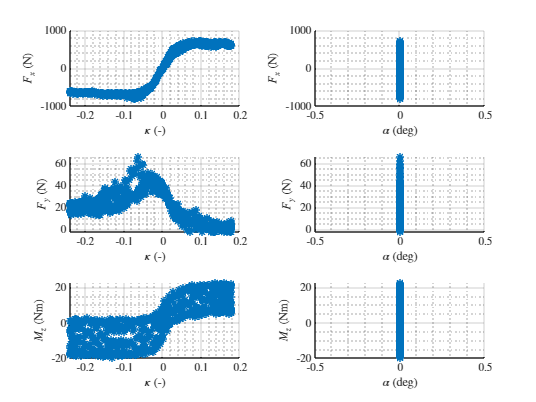

plot_selected_data(TData0);

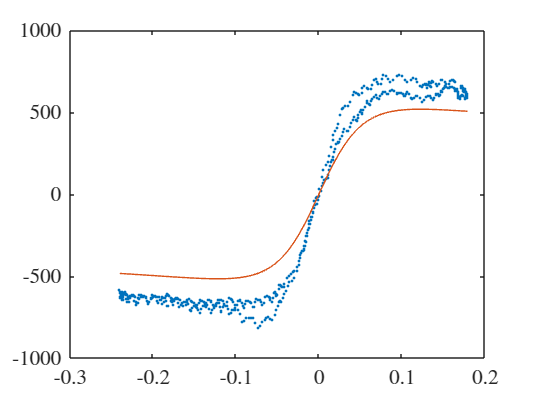


%% FITTING 
% initialise tyre data
tyre_coeffs_pl = initialise_tyre_data_ply(R0, Fz0);

%% Fitting with Fz=Fz_nom= 220N and camber=0  alpha = 0 VX= 10
% ------------------
% long slip

% Fit the coeffs {pCx1, pDx1, pEx1, pEx4, pKx1, pHx1, pVx1}
FZ0 = mean(TData0.FZ);

zeros_vec = zeros(size(TData0.SL));
ones_vec  = ones(size(TData0.SL));

FX0_guess = MF96_FX0_vec(TData0.SL,zeros_vec , zeros_vec, tyre_coeffs_pl.FZ0*ones_vec, tyre_coeffs_pl);

% check guess 
figure()
plot(TData0.SL,TData0.FX,'.')
hold on
plot(TData0.SL,FX0_guess,'-')


% Plot raw data and initial guess
% figure()
% plot(TDataSub.KAPPA,TDataSub.FX,'o')
% hold on
% plot(TDataSub.KAPPA,FX0_guess,'x')

% Guess values for parameters to be optimised
%    [pCx1 pDx1 pEx1 pEx4  pHx1  pKx1  pVx1 
P0_dFz = [  1,   2,   1,  0,   0,   1,   0]; 

% NOTE: many local minima => limits on parameters are fundamentals
% Limits for parameters to be optimised
% 1< pCx1 < 2 
% 0< pEx1 < 1 
%    [pCx1 pDx1 pEx1 pEx4  pHx1  pKx1  pVx1 
lb = [1,   0.1,   0,   0,  -10,    0,   -10];
ub = [2,    4,   1,   1,   10,   100,  10];


KAPPA_vec = TData0.SL;
FX_vec    = TData0.FX;

% check guess
SL_vec = -0.3:0.001:0.3;
FX0_fz_nom_vec = MF96_FX0_vec(SL_vec,zeros(size(SL_vec)) , zeros(size(SL_vec)), ...
                              FZ0.*ones(size(SL_vec)),tyre_coeffs_pl);
% 
% figure
% plot(KAPPA_vec,FX_vec,'.')
% hold on
% plot(SL_vec,FX0_fz_nom_vec,'.')
% 


% LSM_pure_Fx returns the residual, so minimize the residual varying X. It
% is an unconstrained minimization problem 

[P_fz_nom,fval,exitflag] = fmincon(@(P)resid_pure_Fx(P,FX_vec, KAPPA_vec,0,FZ0, tyre_coeffs_pl),...
                               P0_dFz,[],[],[],[],lb,ub)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


P_fz_nom =     1.5387    3.1469    0.0113    0.0806   -0.0000   82.4171   -0.0858


fval = 0.0045

exitflag = 2





% Update tyre data with new optimal values                             
tyre_coeffs_pl.pCx1 = P_fz_nom(1) ; % 1
tyre_coeffs_pl.pDx1 = P_fz_nom(2) ;  
tyre_coeffs_pl.pEx1 = P_fz_nom(3) ;
tyre_coeffs_pl.pEx4 = P_fz_nom(4) ;
tyre_coeffs_pl.pHx1 = P_fz_nom(5) ; 
tyre_coeffs_pl.pKx1 = P_fz_nom(6) ;
tyre_coeffs_pl.pVx1 = P_fz_nom(7) ;

FX0_fz_nom_vec = MF96_FX0_vec(SL_vec,zeros(size(SL_vec)) , zeros(size(SL_vec)), ...
                              FZ0.*ones(size(SL_vec)),tyre_coeffs_pl)

FX0_fz_nom_vec =  -595.7427 -596.0848 -596.4284 -596.7738 -597.1208 -597.4695 -597.8198 -598.1719 -598.5257 -598.8812 -599.2384 -599.5973 -599.9580 -600.3205 -600.6848 -601.0508 -601.4186 -601.7882 -602.1596 -602.5329 -602.9079 -603.2849 -603.6636 -604.0443 -604.4268 -604.8112 -605.1975 -605.5857 -605.9759 -606.3679 -606.7619 -607.1579 -607.5558 -607.9557 -608.3576 -608.7614 -609.1673 -609.5752 -609.9851 -610.3971 -610.8111 -611.2271 -611.6453 -612.0655 -612.4878 -612.9122 -613.3387 -613.7674 -614.1981 -614.6311



figure('Name','Fx0(Fz0)')

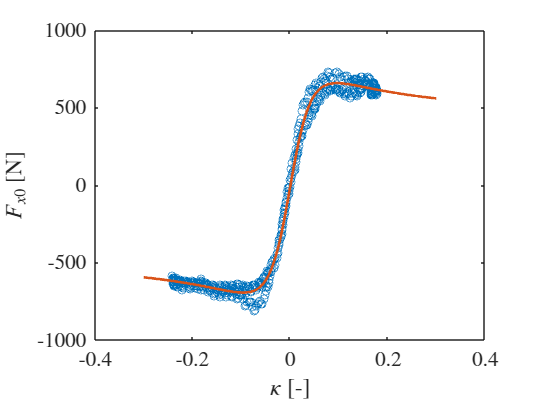

plot(TData0.SL,TData0.FX,'o')
hold on
%plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
plot(SL_vec,FX0_fz_nom_vec,'-','LineWidth',2)
xlabel('$\kappa$ [-]')
ylabel('$F_{x0}$ [N]')

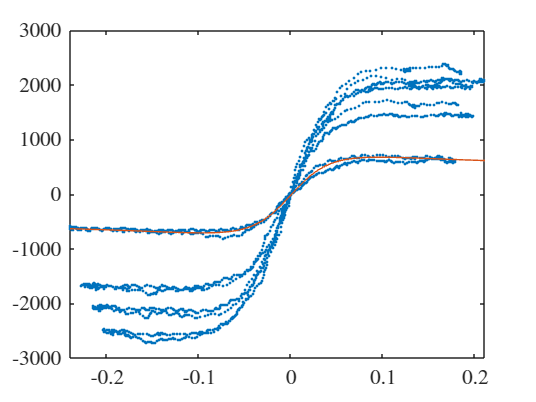


%% Fit coeefficient with variable load
% extract data with variable load
[TDataDFz, ~] = intersect_table_data( SA_0, GAMMA_0 );

% long slip

% Fit the coeffs {pCx1, pDx1, pEx1, pEx4, pKx1, pHx1, pVx1}
%FZ0 = mean(TData0.FZ);

zeros_vec = zeros(size(TDataDFz.SL));
ones_vec  = ones(size(TDataDFz.SL));

FX0_guess = MF96_FX0_vec(TDataDFz.SL,zeros_vec , zeros_vec, tyre_coeffs_pl.FZ0*ones_vec, tyre_coeffs_pl);

% check guess 
figure()
plot(TDataDFz.SL,TDataDFz.FX,'.')
hold on
plot(TDataDFz.SL,FX0_guess,'-')


% Plot raw data and initial guess
% figure()
% plot(TDataSub.KAPPA,TDataSub.FX,'o')
% hold on
% plot(TDataSub.KAPPA,FX0_guess,'x')

% Guess values for parameters to be optimised
%    [pDx2 pEx2 pEx3 pHx2  pKx2  pKx3  pVx2] 
P0_dFz = [  0,   0,   0,  0,   0,   0,   0]; 


% NOTE: many local minima => limits on parameters are fundamentals
% Limits for parameters to be optimised
% 1< pCx1 < 2 
% 0< pEx1 < 1 
%    [pCx1 pDx1 pEx1 pEx4  pHx1  pKx1  pVx1 
lb = [];
ub = [];


KAPPA_vec = TDataDFz.SL;
FX_vec    = TDataDFz.FX;
FZ_vec    = TDataDFz.FZ;

% check guess
SL_vec = -0.3:0.001:0.3;
FX0_dfz_vec = MF96_FX0_vec(SL_vec,zeros(size(SL_vec)) , zeros(size(SL_vec)), ...
                           TDataDFz.FZ,tyre_coeffs_pl);
% 
% figure
% plot(KAPPA_vec,FX_vec,'.')
% hold on
% plot(SL_vec,FX0_dfz_vec,'.')


% LSM_pure_Fx returns the residual, so minimize the residual varying X. It
% is an unconstrained minimization problem 

[P_dfz,fval,exitflag] = fmincon(@(P)resid_pure_Fx_varFz(P,FX_vec, KAPPA_vec,0,FZ_vec, tyre_coeffs_pl),...
                               P0_dFz,[],[],[],[],lb,ub)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


P_dfz =    -0.2496   -0.3619    0.1059    0.0011   -0.0019    0.1536   -0.0256


fval = 0.0029

exitflag = 1


disp(exitflag)

     1



% Change tyre data with new optimal values                             
tyre_coeffs_pl.pDx2 = P_dfz(1) ; % 1
tyre_coeffs_pl.pEx2 = P_dfz(2) ;  
tyre_coeffs_pl.pEx3 = P_dfz(3) ;
tyre_coeffs_pl.pHx2 = P_dfz(4) ;
tyre_coeffs_pl.pKx2 = P_dfz(5) ; 
tyre_coeffs_pl.pKx3 = P_dfz(6) ;
tyre_coeffs_pl.pVx2 = P_dfz(7) ;


res_FX0_dfz_vec = resid_pure_Fx_varFz(P_dfz,FX_vec,SL_vec,0 , FZ_vec,tyre_coeffs_pl)

res_FX0_dfz_vec = 0.5678


tmp_zeros = zeros(size(SL_vec));
tmp_ones = ones(size(SL_vec));


FX0_fz_var_vec1 = MF96_FX0_vec(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_220.FZ)*tmp_ones,tyre_coeffs_pl);
FX0_fz_var_vec2 = MF96_FX0_vec(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_700.FZ)*tmp_ones,tyre_coeffs_pl);
FX0_fz_var_vec3 = MF96_FX0_vec(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_900.FZ)*tmp_ones,tyre_coeffs_pl);
FX0_fz_var_vec4 = MF96_FX0_vec(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_1120.FZ)*tmp_ones,tyre_coeffs_pl);


figure('Name','Fx0(Fz0)')

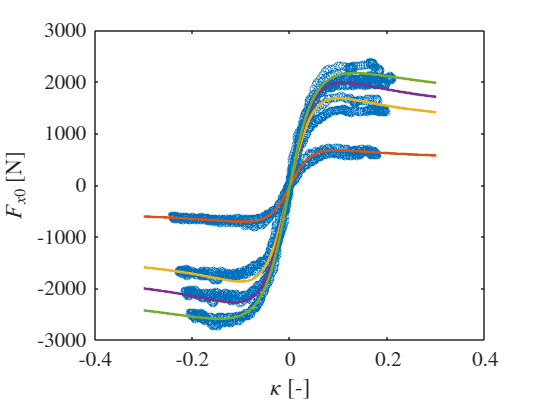

plot(TDataDFz.SL,TDataDFz.FX,'o')
hold on
%plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
%plot(SL_vec,FX0_dfz_vec,'-','LineWidth',2)
plot(SL_vec,FX0_fz_var_vec1,'-','LineWidth',2)
plot(SL_vec,FX0_fz_var_vec2,'-','LineWidth',2)
plot(SL_vec,FX0_fz_var_vec3,'-','LineWidth',2)
plot(SL_vec,FX0_fz_var_vec4,'-','LineWidth',2)

xlabel('$\kappa$ [-]')
ylabel('$F_{x0}$ [N]')



[kappa__x, Bx, Cx, Dx, Ex, SVx] =MF96_FX0_coeffs(0, 0, 0, mean(FZ_220.FZ), tyre_coeffs_pl);
Calfa_vec1_0 = magic_formula_stiffness(kappa__x, Bx, Cx, Dx, Ex, SVx);
[kappa__x, Bx, Cx, Dx, Ex, SVx] =MF96_FX0_coeffs(0, 0, 0, mean(FZ_700.FZ), tyre_coeffs_pl);
Calfa_vec2_0 = magic_formula_stiffness(kappa__x, Bx, Cx, Dx, Ex, SVx);
[kappa__x, Bx, Cx, Dx, Ex, SVx] =MF96_FX0_coeffs(0, 0, 0, mean(FZ_900.FZ), tyre_coeffs_pl);
Calfa_vec3_0 = magic_formula_stiffness(kappa__x, Bx, Cx, Dx, Ex, SVx);
[kappa__x, Bx, Cx, Dx, Ex, SVx] =MF96_FX0_coeffs(0, 0, 0, mean(FZ_1120.FZ), tyre_coeffs_pl);
Calfa_vec4_0 = magic_formula_stiffness(kappa__x, Bx, Cx, Dx, Ex, SVx);

Calfa_vec1 = MF96_CorneringStiffness_x(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_220.FZ)*tmp_ones,tyre_coeffs_pl);
Calfa_vec2 = MF96_CorneringStiffness_x(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_700.FZ)*tmp_ones,tyre_coeffs_pl);
Calfa_vec3 = MF96_CorneringStiffness_x(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_900.FZ)*tmp_ones,tyre_coeffs_pl);
Calfa_vec4 = MF96_CorneringStiffness_x(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_1120.FZ)*tmp_ones,tyre_coeffs_pl);

figure('Name','C_alpha')

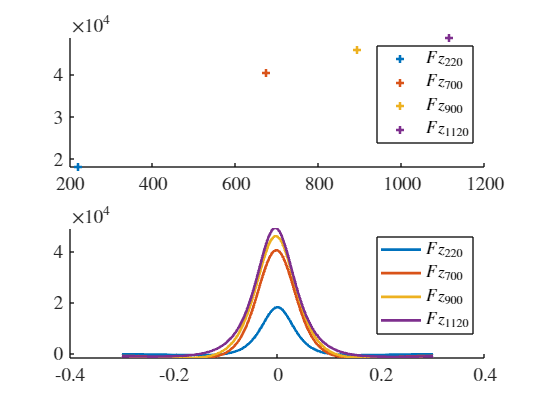

subplot(2,1,1)
hold on
%plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
plot(mean(FZ_220.FZ),Calfa_vec1_0,'+','LineWidth',2)
plot(mean(FZ_700.FZ),Calfa_vec2_0,'+','LineWidth',2)
plot(mean(FZ_900.FZ),Calfa_vec3_0,'+','LineWidth',2)
plot(mean(FZ_1120.FZ),Calfa_vec4_0,'+','LineWidth',2)
legend({'$Fz_{220}$','$Fz_{700}$','$Fz_{900}$','$Fz_{1120}$'})

subplot(2,1,2)
hold on
%plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
plot(SL_vec,Calfa_vec1,'-','LineWidth',2)
plot(SL_vec,Calfa_vec2,'-','LineWidth',2)
plot(SL_vec,Calfa_vec3,'-','LineWidth',2)
plot(SL_vec,Calfa_vec4,'-','LineWidth',2)
legend({'$Fz_{220}$','$Fz_{700}$','$Fz_{900}$','$Fz_{1120}$'})

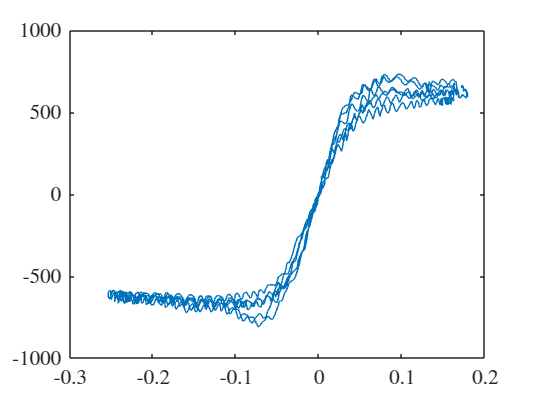



%% Fit coefficient with variable camber

% extract data with variable load
[TDataGamma, ~] = intersect_table_data( SA_0, FZ_220 );

% Fit the coeffs { pDx3}

% Guess values for parameters to be optimised
P0_dFz = [0]; 

% NOTE: many local minima => limits on parameters are fundamentals
% Limits for parameters to be optimised
% 1< pCx1 < 2 
% 0< pEx1 < 1 
%lb = [0, 0,  0, 0,  0,  0,  0];
%ub = [2, 1e6,1, 1,1e1,1e2,1e2];
lb = [];
ub = [];


zeros_vec = zeros(size(TDataGamma.SL));
ones_vec  = ones(size(TDataGamma.SL));

KAPPA_vec = TDataGamma.SL;
GAMMA_vec = TDataGamma.IA; 
FX_vec    = TDataGamma.FX;
FZ_vec    = TDataGamma.FZ;

figure()
plot(KAPPA_vec,FX_vec);



% LSM_pure_Fx returns the residual, so minimize the residual varying X. It
% is an unconstrained minimization problem 
[P_varGamma,fval,exitflag] = fmincon(@(P)resid_pure_Fx_varGamma(P,FX_vec, KAPPA_vec,GAMMA_vec,tyre_coeffs_pl.FZ0, tyre_coeffs_pl),...
                               P0_dFz,[],[],[],[],lb,ub)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


P_varGamma = 18.4364

fval = 0.0062

exitflag = 1


% Change tyre data with new optimal values                             
tyre_coeffs_pl.pDx3 = P_varGamma(1) ; % 1

FX0_varGamma_vec = MF96_FX0_vec(KAPPA_vec,zeros_vec , GAMMA_vec, tyre_coeffs_pl.FZ0*ones_vec,tyre_coeffs_pl)

FX0_varGamma_vec =   630.1731
  630.1742
  630.1739
  630.1731
  630.1731
  630.1734
  630.7898
  631.4074
  632.0276
  632.6481



figure('Name','Fx0 vs Gamma')

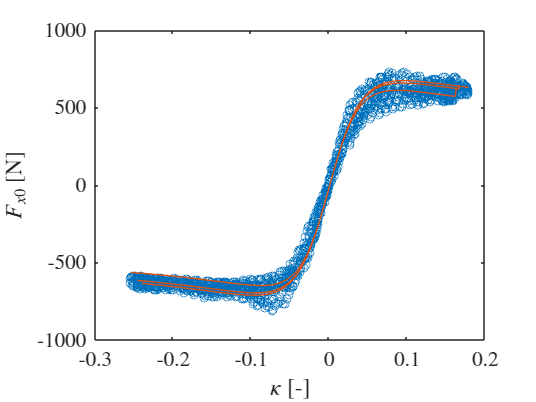

plot(KAPPA_vec,TDataGamma.FX,'o')
hold on
plot(KAPPA_vec,FX0_varGamma_vec,'-')
xlabel('$\kappa$ [-]')
ylabel('$F_{x0}$ [N]')

% Calculate the residuals with the optimal solution found above
res_Fx0_varGamma  = resid_pure_Fx_varGamma(P_varGamma,FX_vec, KAPPA_vec,GAMMA_vec,tyre_coeffs_pl.FZ0, tyre_coeffs_pl);

% R-squared is 
% 1-SSE/SST
% SSE/SST = res_Fx0_nom

% SSE is the sum of squared error,  SST is the sum of squared total
fprintf('R-squared = %6.3f\n',1-res_Fx0_varGamma);

R-squared =  0.994




[kappa__x, Bx, Cx, Dx, Ex, SVx] = MF96_FX0_coeffs(0, 0, GAMMA_vec(3), tyre_coeffs_pl.FZ0, tyre_coeffs_pl);
% 
fprintf('Bx      = %6.3f\n',Bx);

Bx      = 17.021


fprintf('Cx      = %6.3f\n',Cx);

Cx      =  1.539


fprintf('mux      = %6.3f\n',Dx/tyre_coeffs_pl.FZ0);

mux      =  3.147


fprintf('Ex      = %6.3f\n',Ex);

Ex      =  0.011


fprintf('SVx     = %6.3f\n',SVx);

SVx     = -18.871


fprintf('kappa_x = %6.3f\n',kappa__x);

kappa_x = -0.000


fprintf('Kx      = %6.3f\n',Bx*Cx*Dx/tyre_coeffs_pl.FZ0);

Kx      = 82.417



% Longitudinal stiffness
Kx_vec = zeros(size(load_vec));

Unrecognized function or variable 'load_vec'.

for i = 1:length(load_vec)
  [kappa__x, Bx, Cx, Dx, Ex, SVx] = MF96_FX0_coeffs(0, 0, 0, load_vec(i), tyre_data);
  Kx_vec(i) = Bx*Cx*Dx/tyre_data.Fz0;
end

figure('Name','Kx vs Fz')
plot(load_vec,Kx_vec,'o-')

% Save tyre data structure to mat file

save(['tyre_' data_set,'.mat'],'tyre_coeffs_pl');




